clear
load data2.mat
n=length(data.CzasLokalnyUTC0000)

n = 516459


T=5; %[s]
fs=1/T; %[Hz]
t_all=T*(0:n-1);

Skraplacz=0.1*data.Skraplacz;
Kompresor1=data.Kompresor1;
Parownik1=0.1*data.Parownik1;
Wlot=0.1*data.Wlot;
TemperaturaOtoczenia=0.1*data.TemperaturaOtoczenia;
Rozmraanie=data.Rozmraanie;
WentylatorParownika=data.WentylatorParownika;
ZawrOdszraniania=data.ZawrOdszraniania;

X_all=[ZawrOdszraniania,Kompresor1,WentylatorParownika,Rozmraanie,...
    TemperaturaOtoczenia,Skraplacz,Wlot,Parownik1]';

[X,~]  = GetRidOfNans(X_all);

h10th=10*60*60*fs;
h15th=15*60*60*fs;
t=T*(h10th:h15th);
X=X';
X=X(:,h10th:h15th);
size(X)

ans =            8        3601


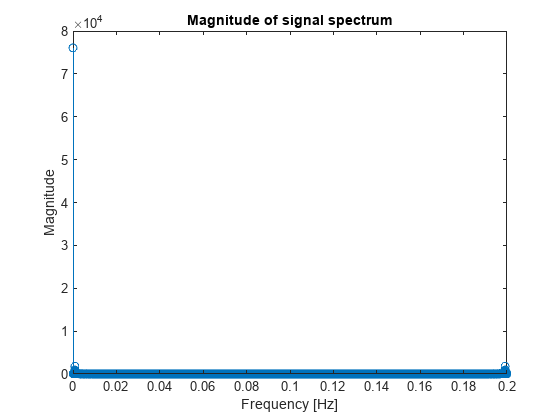

n=length(t);
X_toFilter=X(5:8,:);
threshold=[0,5;0,5;-5,0;-5,0];
for i = 1:4
X_filtered(i,:) = InterpolateData(X_toFilter(i,:),threshold(i,:),t);
end

x=X(2,:);
y=X_filtered(3,:);
Ta=X_filtered(1,:);

R=-99;
C=-98;
G=-1.07;
x0=y(1);
y1=ModelFunction(-x',Ta',G,R,C,t,x0);
magaxis = 0:fs/length(y):fs-fs/length(y);
Y=fft(y);
mag=abs(Y);
ph=angle(Y);
stem(magaxis,mag)
xlabel('Frequency [Hz]')
ylabel('Magnitude')
title('Magnitude of signal spectrum')

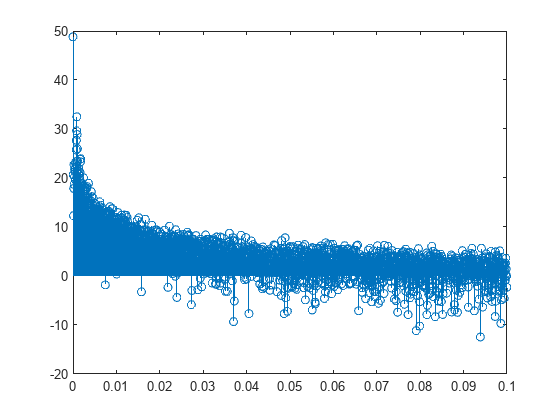

stem(magaxis(1:(n+1)/2),10*log10(mag(1:(n+1)/2)))

We identify the dominant frequency

[~, idx] = max(mag(2:floor(n/2)+1));
idx=idx+1;
f1=magaxis(idx);
phase1 = ph(idx);

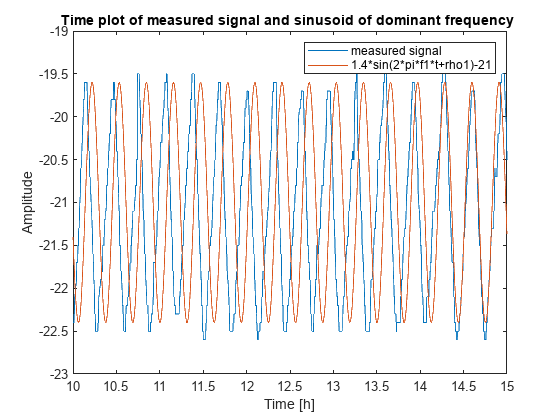

rho1=phase1;
x=1.4*sin(2*pi*f1*t+rho1)-21;
figure
plot(t/(60*60),y);hold on
plot(t/(60*60),x);hold off
title('Time plot of measured signal and sinusoid of dominant frequency ')
legend('measured signal','1.4*sin(2*pi*f1*t+rho1)-21')
xlabel('Time [h]')
ylabel('Amplitude')

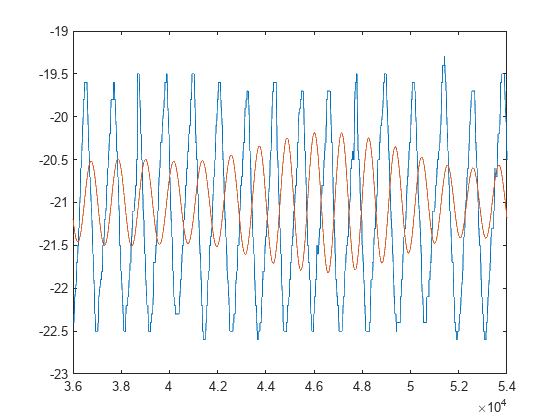

y2=(1/n)*abs(Y(16:18))*sin(2*pi*magaxis(16:18)'*t+angle(Y(16:18)'))-21;
figure
plot(t,y);hold on
plot(t,y2);hold off

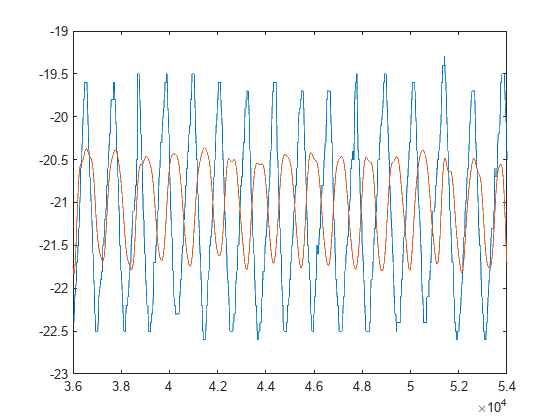

y2=(1/n)*abs(Y(1:60))*sin(2*pi*magaxis(1:60)'*t+angle(Y(1:60)'))-21;
figure
plot(t,y);hold on
plot(t,y2);hold off

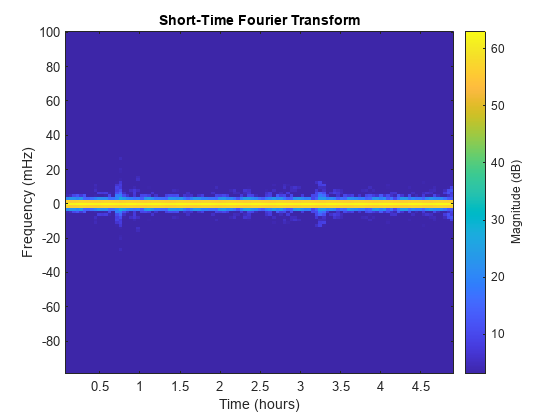

window=750;
overlap=round(0.2*window);
stft(y,fs);